clear;
rmdir('.\DataSet\', 's');
mkdir('.\DataSet\');

% 配置
config;
%-----------------------------
% 产生信号
source;
tag;
global y_sig;
y_sig = y_source .* y_tag;

global Length;
global Width;

## 房间内的随机点

N_inside = 50;
x = Width * rand(1, N_inside);
y = Length * rand(1, N_inside);

% 计算三个距离
[d1, d2, d3] = xy2d(x, y);

single_run(d1, d2, d3, false, 'inside');

delta t is
   1.0e-07 *

  列 1 至 16

    0.0821    0.1178    0.1118    0.1216    0.1759    0.1083    0.0130    0.1231    0.0704    0.1013    0.1427    0.1077    0.0100    0.0577    0.0268    0.1896

  列 17 至 32

    0.0803    0.1186    0.1079    0.0234    0.0253    0.0306    0.1973    0.0446    0.0283    0.1402    0.1099    0.1142    0.1818    0.1375    0.0203    0.1099

  列 33 至 48

    0.1792    0.0153    0.0801    0.1781    0.0444    0.1102    0.0151    0.1336    0.0591    0.0198    0.2000    0.1184    0.1835    0.1437    0.1273    0.0883

  列 49 至 50

    0.0202    0.0666



## 房间外的随机点

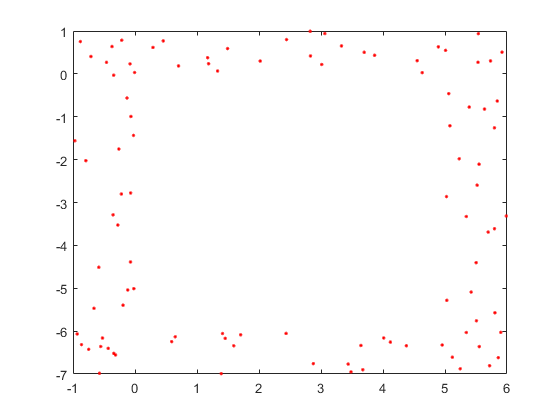

% 1/4 的数量
N_outside = 25;
x0 = rand(4, N_outside);
y0 = rand(4, N_outside);

x0 = [((Width / 2 + 1) * x0(:, 1:floor(N_outside / 2)))   (Width / 2 + x0(:, round(N_outside / 2) : end))];
y0 = [(Length / 2 + y0(:, 1:floor(N_outside / 2)))  ((Length / 2 + 1) * y0(:, round(N_outside / 2): end))];

x0(1,:) = -1 * x0(1, :);
x0(3,:) = -1 * x0(3, :);
y0(3,:) = -1 * y0(3, :);
y0(4,:) = -1 * y0(4, :);

% 坐标原点
x0 = x0 - (-1) * (Width / 2) * ones(size(x0));
y0 = y0 - 1 * (Length / 2) * ones(size(y0));

% 画出散点
% TODO: bugfix --- 点都集中在四个角落了，需要分散到边边上
figure; plot(x0,y0,'r.');


% 计算三个距离
[d1_0, d2_0, d3_0] = xy2d(x0, y0);
single_run(d1_0, d2_0, d3_0, false, 'outside');

delta t is
   1.0e-07 *

  列 1 至 16

    0.0367    0.0261    0.0496    0.0538    0.0274    0.0236    0.0866    0.0270    0.0547    0.0632    0.0811    0.0431    0.1951    0.1302    0.0442    0.1107
    0.1615    0.1114    0.0996    0.1257    0.1515    0.2112    0.2112    0.1999    0.2646    0.1301    0.1123    0.2540    0.3470    0.2941    0.2192    0.3288
    0.4304    0.4135    0.4355    0.4756    0.4280    0.4302    0.4692    0.4204    0.4227    0.4207    0.4149    0.4111    0.2267    0.3071    0.3636    0.2417
    0.5341    0.4829    0.5098    0.5084    0.4960    0.5126    0.4741    0.5536    0.4954    0.4831    0.5094    0.4746    0.5601    0.5655    0.5005    0.4036

  列 17 至 25

    0.0340    0.0344    0.1274    0.1516    0.0403    0.0375    0.0858    0.1932    0.0642
    0.3358    0.2721    0.2740    0.3109    0.2709    0.2413    0.3081    0.2472    0.2885
    0.4378    0.2973    0.4402    0.4268    0.3380    0.4149    0.3401    0.3701    0.4333
    0.4617    0.5296    0.5350  



% 保存样本点
filename = '.\DataSet\sample.mat'

filename = '.\DataSet\sample.mat'

save(filename, 'N_inside', 'N_outside', 'x', 'y', 'd1', 'd2', 'd3', 'x0', 'y0', 'd1_0', 'd2_0', 'd3_0');

## 数据预处理

% [] = preproc(filename, i, draw, isBeacon)
for i=1: N_inside
    preproc('i_sig_rx', i, false, 'inside');
end

% outside
for i=1: 4 * N_outside
    preproc('o_sig_rx', i, false, 'outside');
end